# Vector & Matrices

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-04-30

## Creating a Row and Column Vector

### Row vector

% row vector
row_vec1 = [1 2 3 4]; % sparated by space
row_vec2 = [1   2   3   4]; % separated by multiple spaces
row_vec3 = [1, 2, 3, 4]; % separated by commas
row_vec4 = 1:4; % use a colon operator
row_vec5 = [1:4]; % okay with putting square brackets

% they are identical
row_vec1

row_vec1 =      1     2     3     4


row_vec2

row_vec2 =      1     2     3     4


row_vec3

row_vec3 =      1     2     3     4


row_vec4

row_vec4 =      1     2     3     4


row_vec5

row_vec5 =      1     2     3     4


### Column vector

col_vec1 = [5;4;3];
col_vec2 = 5:-1:3; % not a column vector
col_vec3 = transpose(5:-1:3);
col_vec4 = col_vec2';

% col_vec1 is the same with col_vec3 and col_vec4
% col_vec1 is NOT the same with col_vec2
col_vec1

col_vec1 =      5
     4
     3


col_vec2

col_vec2 =      5     4     3


col_vec3

col_vec3 =      5
     4
     3


col_vec4

col_vec4 =      5
     4
     3


### Concatenation

vec = [1 2 3 7];
vec1 = [vec 8 7]; % adding elements
vec2 = [vec [8 7]]; % adding a row vector
vec3 = [vec [8;7]']; % adding a column vector after transposing
vec4 = [vec';8;7]';
% adding a column vector to the column vector (vec1') 
% and transpose an entire column vector
vec5 = vec;
vec5(5:6) = [8 7]; % valid code but not recomended

vec6 = cat(2, vec, [8 7]); % doc cat
% 1: column, 2: row, 3: depth 

% identical
vec1

vec1 =      1     2     3     7     8     7


vec2

vec2 =      1     2     3     7     8     7


vec3

vec3 =      1     2     3     7     8     7


vec4

vec4 =      1     2     3     7     8     7


vec5

vec5 =      1     2     3     7     8     7


### Modifying vectors

vec = [1 2 37];
vec

vec =      1     2    37


vec(1) = 5;
vec

vec =      5     2    37


vec(1:3) = [6 7 8];
vec

vec =      6     7     8


% vec(6) % error due to refer unassigned value

## Creating a Matrix

### Assinging values

mat1 = [1 2 3;4 5 6;7 8 9]; % direct assignment (concatenate rows)
mat2 = [1:3;4:6;7:9]; % use a colon operator
mat3 = [[1;4;7] [2;5;8] [3;6;9]]; % concatenate columns
mat4 = reshape(1:9, 3, 3)'; % will learn

% identical
mat1

mat1 =      1     2     3
     4     5     6
     7     8     9


mat2

mat2 =      1     2     3
     4     5     6
     7     8     9


mat3

mat3 =      1     2     3
     4     5     6
     7     8     9


mat4

mat4 =      1     2     3
     4     5     6
     7     8     9


### Use built-in functions to create matrices

mat1_0 = [0 0 0; 0 0 0; 0 0 0];
mat2_0 = zeros(3,3);
mat1_0

mat1_0 =      0     0     0
     0     0     0
     0     0     0


mat2_0

mat2_0 =      0     0     0
     0     0     0
     0     0     0



mat1_1 = [1 1 1; 1 1 1; 1 1 1];
mat2_1 = ones(3,3);
mat1_1

mat1_1 =      1     1     1
     1     1     1
     1     1     1


mat2_1

mat2_1 =      1     1     1
     1     1     1
     1     1     1



rand(3,3) % random matrix where its elements are real number within (0, 1)

ans =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575



mat1_random = randi([1 10], 3, 3); % random integer
mat1_random

mat1_random =     10    10     2
     2     5     5
    10     9    10



% in general, it is receommend that matrices are created 
% using built-in functions because we can determine the size of the matrices 
% in beginning. 

mat1 = [1 2 3;4 5 6;7 8 9]; 

mat2 = zeros(3,3);
mat2(1,:) = [1 2 3];
mat2(2,:) = [4 5 6];
mat2(3,:) = [7 8 9];

% comment: if the size of matrices are large, the second method can avoid
% or easily detect a potential mistake.

### Matrix dimension

mat1 = rand(3,5);
[sc1, sr1] = size(mat1); % use 'size' function; doc size
n_elem1 = sc1 * sr1;

sc2 = size(mat1,1); % doc size 
sr2 = size(mat1,2); % 1 is a column, 2 is a row direction
n_elem2 = numel(mat1);

sc3 = numel(mat1(:,1)); % return a size of a column in mat1
sr3 = numel(mat1(1,:)); % return a size of a row in mat1
n_elem3 = numel(mat1); % return the total # of elements in mat1

% they are identical
[sc1 sc2 sc3]

ans =      3     3     3


[sr1 sr2 sr3]

ans =      5     5     5


[n_elem1 n_elem2 n_elem3]

ans =     15    15    15


### Modifying matrix

mat0 = zeros(5,5);
row_vec = 1:5;
col_vec = 6:10;
mat_sub = ones(2,3);

% initialize all mat# with mat0 (a 5x5 zero matrix)
mat01 = mat0; mat02 = mat0; mat03 = mat0; 
mat04 = mat0; mat05 = mat0; mat06 = mat0; 
mat07 = mat0; mat08 = mat0; mat09 = mat0; 
mat10 = mat0; 

% evaluate your resulting matrix
mat01(2,:) = row_vec;
mat02(:,3) = col_vec;
mat03(1:2,1:3) = mat_sub;
mat04(2:4,1:2) = mat_sub';
mat05(1:4,1) = col_vec(1:4);
mat06(1:4,1) = row_vec(1:4)';
mat07(2:end, 1) = col_vec(2:end);
mat08(2:end, end) = row_vec(2:end)';
mat09(1:4, 1:2) = 3;
mat10(1,:) = 5;

mat01

mat01 =      0     0     0     0     0
     1     2     3     4     5
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


mat02

mat02 =      0     0     6     0     0
     0     0     7     0     0
     0     0     8     0     0
     0     0     9     0     0
     0     0    10     0     0


mat03

mat03 =      1     1     1     0     0
     1     1     1     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


mat04

mat04 =      0     0     0     0     0
     1     1     0     0     0
     1     1     0     0     0
     1     1     0     0     0
     0     0     0     0     0


mat05

mat05 =      6     0     0     0     0
     7     0     0     0     0
     8     0     0     0     0
     9     0     0     0     0
     0     0     0     0     0


mat06

mat06 =      1     0     0     0     0
     2     0     0     0     0
     3     0     0     0     0
     4     0     0     0     0
     0     0     0     0     0


mat07

mat07 =      0     0     0     0     0
     7     0     0     0     0
     8     0     0     0     0
     9     0     0     0     0
    10     0     0     0     0


mat08

mat08 =      0     0     0     0     0
     0     0     0     0     2
     0     0     0     0     3
     0     0     0     0     4
     0     0     0     0     5


mat09

mat09 =      3     3     0     0     0
     3     3     0     0     0
     3     3     0     0     0
     3     3     0     0     0
     0     0     0     0     0


mat10

mat10 =      5     5     5     5     5
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


### Linear indexing

This is very important to understand how the matlab functions work. 

You should be used to convert a matrix to a linearly indexed vector and vice vercsa

% introduce 'reshape': doc reshape
vec0 = 1:10;
mat0 = reshape(vec0, 2, 5);
mat1 = reshape(vec0, 2, []); % same with mat0. 
% The second dimention is determined based on the # of element

% mat_error = reshape(vec0, 3,5); % error: dimension mismatch

mat0

mat0 =      1     3     5     7     9
     2     4     6     8    10


mat1

mat1 =      1     3     5     7     9
     2     4     6     8    10


clearvars vec0 mat0 mat1

% linear indexing
mat00 = zeros(4,4);
row_vec = 1:4;
col_vec = transpose(5:8);
mat_sub = [1 2 3;4 5 6];

% initialize all mat# with mat0 (a 5x5 zero matrix)
mat01 = mat00; mat02 = mat00; mat03 = mat00; 
mat04 = mat00; mat05 = mat00; mat06 = mat00; 
mat07 = mat00; mat08 = mat00; 

% You should understand how they work
mat01(1:4) = row_vec;
mat02(1:4) = col_vec;
mat03(1:5) = [col_vec; 10];
mat04(1:6) = mat_sub; % unwind automatically
mat05(1:6) = mat_sub'; % unwind automatically 
% mat_error(1:7) =  mat_sub; % because of mismatching # of elements
mat06(8:11) = row_vec;
mat07([1 3 5 6]) = col_vec;
mat08([6 5 3 1]) = col_vec;

mat09 = reshape(1:16, 4, 4);
mat09(16:-1:1) = 1:16;

mat10 = reshape(1:16, 4, 4);
mat10(16:-1:1) = mat10(:); % this's cool!


mat00

mat00 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


row_vec

row_vec =      1     2     3     4


col_vec

col_vec =      5
     6
     7
     8


mat_sub

mat_sub =      1     2     3
     4     5     6



mat01

mat01 =      1     0     0     0
     2     0     0     0
     3     0     0     0
     4     0     0     0


mat02

mat02 =      5     0     0     0
     6     0     0     0
     7     0     0     0
     8     0     0     0


mat03

mat03 =      5    10     0     0
     6     0     0     0
     7     0     0     0
     8     0     0     0


mat04

mat04 =      1     3     0     0
     4     6     0     0
     2     0     0     0
     5     0     0     0


mat05

mat05 =      1     5     0     0
     2     6     0     0
     3     0     0     0
     4     0     0     0


mat06

mat06 =      0     0     2     0
     0     0     3     0
     0     0     4     0
     0     1     0     0


mat07

mat07 =      5     7     0     0
     0     8     0     0
     6     0     0     0
     0     0     0     0


mat08

mat08 =      8     6     0     0
     0     5     0     0
     7     0     0     0
     0     0     0     0


mat09

mat09 =     16    12     8     4
    15    11     7     3
    14    10     6     2
    13     9     5     1


mat10

mat10 =     16    12     8     4
    15    11     7     3
    14    10     6     2
    13     9     5     1


### Empty vector

vec1 = 1:5;
vec1(end) = []; % remove the last element (become 1x4)
vec1(2) = []; % remove the second element (become 1x3)

% vec1(5) % errors

mat1 = reshape(1:16, 4, 4);
mat1(:,3) = []; % remove the 3rd column in 
mat1(2, :) = [];
% mat1(2, 1) = [] % error

vec1

vec1 =      1     3     4


mat1

mat1 =      1     5    13
     3     7    15
     4     8    16


### 3D matrix

% please think about what set of elements can be accessed using the
% following indexing
mat3D = reshape(1:120, 8, 5, 3);

mat3D(:,:,1)

ans =      1     9    17    25    33
     2    10    18    26    34
     3    11    19    27    35
     4    12    20    28    36
     5    13    21    29    37
     6    14    22    30    38
     7    15    23    31    39
     8    16    24    32    40


mat3D(:,:,2)

ans =     41    49    57    65    73
    42    50    58    66    74
    43    51    59    67    75
    44    52    60    68    76
    45    53    61    69    77
    46    54    62    70    78
    47    55    63    71    79
    48    56    64    72    80


mat3D(:,:,3)

ans =     81    89    97   105   113
    82    90    98   106   114
    83    91    99   107   115
    84    92   100   108   116
    85    93   101   109   117
    86    94   102   110   118
    87    95   103   111   119
    88    96   104   112   120



mat1 = mat3D(:,1,1); % first column in depth
mat2 = mat3D(1,1,:); % first element in depth
mat3 = mat3D(1,:,1); % first row in the 1st dpeth
mat4 = mat3D(2,:,:); % second row in depth
mat5 = mat3D(:,2,:); % second column in depth

mat1

mat1 =      1
     2
     3
     4
     5
     6
     7
     8


mat2

mat2 = mat2(:,:,1) =

     1


mat2(:,:,2) =

    41


mat2(:,:,3) =

    81


mat3

mat3 =      1     9    17    25    33


mat4

mat4 = mat4(:,:,1) =

     2    10    18    26    34


mat4(:,:,2) =

    42    50    58    66    74


mat4(:,:,3) =

    82    90    98   106   114


mat5

mat5 = mat5(:,:,1) =

     9
    10
    11
    12
    13
    14
    15
    16


mat5(:,:,2) =

    49
    50
    51
    52
    53
    54
    55
    56


mat5(:,:,3) =

    89
    90
    91
    92
    93
    94
    95
    96


### Scalar operations

mat1 = ones(3,3); 
mat2 = mat1 + 3; % add 3 to all elements in mat1
mat3 = mat1 + ones(3,3)*3; % it is the same with the above

mat4 = zeros(size(mat1));
mat4(:) = 4; % modify all elements to 4

mat2

mat2 =      4     4     4
     4     4     4
     4     4     4


mat3

mat3 =      4     4     4
     4     4     4
     4     4     4


mat4

mat4 =      4     4     4
     4     4     4
     4     4     4


### Array operations

matA = ones(3,3)*6;
matB = ones(3,3)*2;

mat1 = matA + matB; % matrix addition
mat2 = matB*4; % scalar multiplication
mat3 = matA - matB; % matrix subtraction
mat4 = matA.^2;  % array exponetial

matC = ones(4,4);
matC(1:2,1:2) = 2; % concatenation
macC(3:4,3:4) = 3;

matD = ones(4,4)*12;

mat5 = matC + matD;
mat6 = matC - matD; 
mat7 = matC.*matD; % array multiplication (element-wise multiplication)
mat8 = matD./matC; % array division (element-wise division)


matA

matA =      6     6     6
     6     6     6
     6     6     6


matB

matB =      2     2     2
     2     2     2
     2     2     2


matC

matC =      2     2     1     1
     2     2     1     1
     1     1     1     1
     1     1     1     1


matD

matD =     12    12    12    12
    12    12    12    12
    12    12    12    12
    12    12    12    12



mat1

mat1 =      8     8     8
     8     8     8
     8     8     8


mat2

mat2 =      8     8     8
     8     8     8
     8     8     8


mat3

mat3 =      4     4     4
     4     4     4
     4     4     4


mat4

mat4 =     36    36    36
    36    36    36
    36    36    36


mat5

mat5 =     14    14    13    13
    14    14    13    13
    13    13    13    13
    13    13    13    13


mat6

mat6 =    -10   -10   -11   -11
   -10   -10   -11   -11
   -11   -11   -11   -11
   -11   -11   -11   -11


mat7

mat7 =     24    24    12    12
    24    24    12    12
    12    12    12    12
    12    12    12    12


mat8

mat8 =      6     6    12    12
     6     6    12    12
    12    12    12    12
    12    12    12    12


## Logical Vectors and Operations

This is very important topics to write very efficient code and understanding the structure of the built-in functions

### Logical vectors

vec1 = 2:11;

logi_vec = ones(1,10, 'logical'); % all true 
logi_vec([3 5 7]) = false; % assign false logical values

vec2 = vec1(logi_vec); % access all values except values at 3, 5, and 7 locations
vec3 = vec1(~logi_vec); % access values at 3, 5, and 7 locations 

logi_equal_5 = (vec1==5); 
vec4 = vec1(logi_equal_5); % values of 5

logi_larger_5 = (vec1>5);
vec5 = vec1(logi_larger_5); % values more than 5

logi_smaller_5 = (vec1<5);
vec6 = vec1(logi_smaller_5); % values less than 5

mat1 = reshape(vec1, 2, 5);
vec7 = mat1(logi_equal_5);
vec8 = mat1(logi_larger_5);
vec9 = mat1(logi_smaller_5);
% comment: use same logical vectors to access values in a matrix

vec1

vec1 =      2     3     4     5     6     7     8     9    10    11


vec2

vec2 =      2     3     5     7     9    10    11


vec3

vec3 =      4     6     8


vec4

vec4 = 5

vec5

vec5 =      6     7     8     9    10    11


vec6

vec6 =      2     3     4



mat1

mat1 =      2     4     6     8    10
     3     5     7     9    11


vec7

vec7 = 5

vec8

vec8 =      6     7     8     9    10    11


vec9

vec9 =      2     3     4


### Logical functions

**Q: How to check if there is a certain number in a vector? Let's say 5 in mat1. **

vec1 = 2:11;
mat1 = reshape(vec1, 2, 5);

tmp1 = (vec1 == 5);
is_there_five_v1 = logical(sum(tmp1));

is_there_five_v2 = any(vec1==5);
is_there_five_v3 = ~all(vec1~=5);
is_there_five_v4 = any(ismember(vec1, 5)); % doc ismember
% comment: 'ismember' supports various input array forms.

tmp4 = find(vec1==5);
is_there_five_v5 = (numel(tmp4)~=0);

tmp6 = (mat1 == 5);
is_there_five_v6 = logical(sum(tmp6, 'all'));
is_there_five_v7 = logical(sum(tmp6(:)));

tmp8 = find(mat1 ==5);
is_there_five_v8 = (numel(tmp8)~=0);

is_there_five_v1

is_there_five_v1 = logical
   1


is_there_five_v2

is_there_five_v2 = logical
   1


is_there_five_v3

is_there_five_v3 = logical
   1


is_there_five_v4

is_there_five_v4 = logical
   1


is_there_five_v5

is_there_five_v5 = logical
   1


is_there_five_v6

is_there_five_v6 = logical
   1


is_there_five_v7

is_there_five_v7 = logical
   1


### Elemenet-wise logical operations

Elemenet-wise logical operations

mat1 = reshape(0:11, 3, 4);
mat2 = mat1;
mat2(1,3) = 0;

logi_mat1 = (mat1 | mat2)

logi_mat1 = 3×4 logical array
   0   1   1   1
   1   1   1   1
   1   1   1   1


logi_mat2 = logical(logical(mat1) + logical(mat2))

logi_mat2 = 3×4 logical array
   0   1   1   1
   1   1   1   1
   1   1   1   1



logi_mat3 = (mat1 & mat2)

logi_mat3 = 3×4 logical array
   0   1   0   1
   1   1   1   1
   1   1   1   1


logi_mat4 = logical(mat1 .* mat2)

logi_mat4 = 3×4 logical array
   0   1   0   1
   1   1   1   1
   1   1   1   1


## Matrix Multiplication

### Matrix times a vector (numeric)

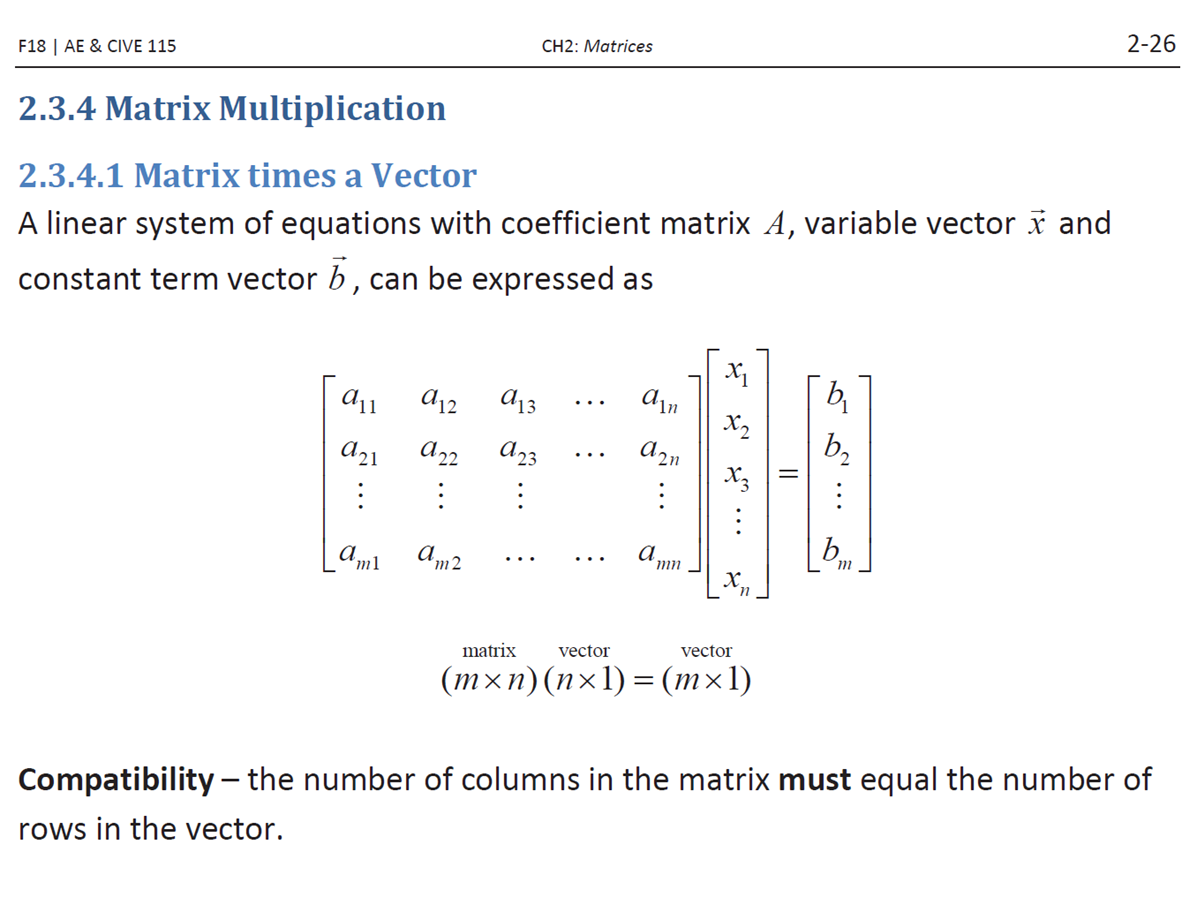

matA = reshape(1:9,3,3); 
vecA = [1;2;3];

vec1 = matA*vecA; % matrix times a vector

vec2 = zeros(3,1);
vec2(1) = matA(1,:)*vecA; % row vector x column vector
vec2(2) = matA(2,:)*vecA;
vec2(3) = matA(3,:)*vecA;

vec3 = zeros(3,1);
vec3(1) = sum(matA(1,:)'.*vecA); % element-wise operation (vector, vector)
vec3(2) = sum(matA(2,:)'.*vecA);
vec3(3) = sum(matA(3,:)'.*vecA);

vec4 = zeros(3,1);
vec4(1) = dot(matA(1,:)', vecA); % dot product
vec4(2) = dot(matA(2,:)', vecA);
vec4(3) = dot(matA(3,:)', vecA);

vec5 = sum(matA.*[vecA';vecA';vecA'],2); % element-wise operation (matrix, matrix)

% identical
vec1

vec1 =     30
    36
    42


vec2

vec2 =     30
    36
    42


vec3

vec3 =     30
    36
    42


vec4

vec4 =     30
    36
    42


vec5

vec5 =     30
    36
    42


### Matrix times a vector (symbolic)

Let's understand above expression using symbolic experessions (will learn soon) 

clear;
syms a11 a12 a13 a21 a22 a23 a31 a32 a33
syms x1 x2 x3
A = [a11 a12 a13; a21 a22 a23; a31 a32 a33];
x = [x1;x2;x3];

vec1_syms = A*x;

vec2_syms(1,1) = A(1,:)*x;
vec2_syms(2,1) = A(2,:)*x;
vec2_syms(3,1) = A(3,:)*x;

vec3_syms(1,1) = sum(transpose(A(1,:)).*x);
vec3_syms(2,1) = sum(transpose(A(2,:)).*x);
vec3_syms(3,1) = sum(transpose(A(3,:)).*x);

vec5_syms = sum(A .* transpose([x x x]), 2);

vec1_syms

$$vec1\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec2_syms

$$vec2\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec3_syms

$$vec3\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

vec5_syms

$$vec5\_syms = \left(\begin{array}{c} a_{11}\,x_{1}+a_{12}\,x_{2}+a_{13}\,x_{3}\\ a_{21}\,x_{1}+a_{22}\,x_{2}+a_{23}\,x_{3}\\ a_{31}\,x_{1}+a_{32}\,x_{2}+a_{33}\,x_{3} \end{array}\right)$$

### 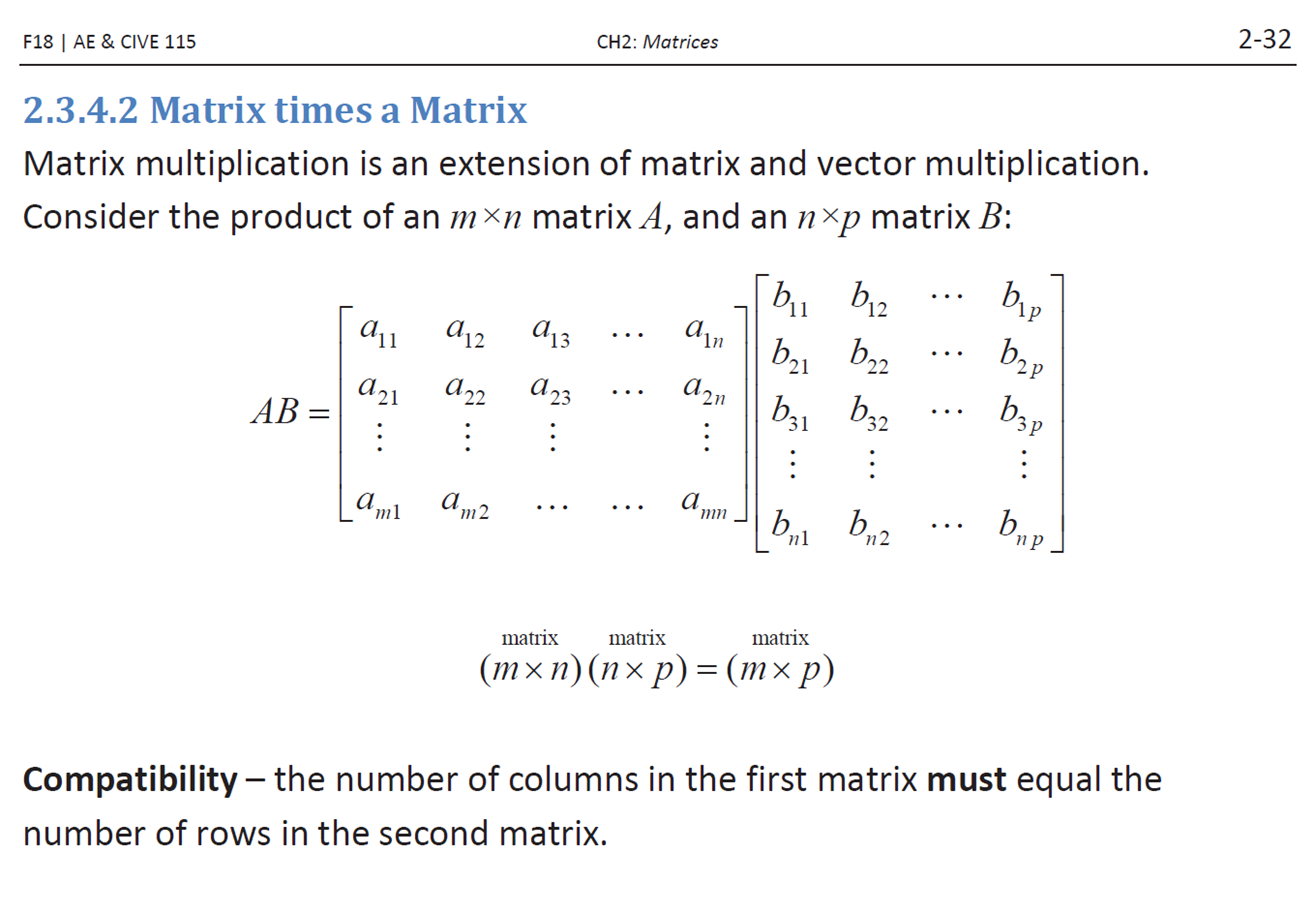

### Matrix times a matrix (numeric)

matA = reshape(1:9,3,3); 
matB = reshape(10:18,3,3); 

mat1 = matA*matB; % matrix times a matrix

mat2 = zeros(3,3);
mat2(:,1) = matA*matB(:,1); % matrix x column vector
mat2(:,2) = matA*matB(:,2);
mat2(:,3) = matA*matB(:,3);

mat3 = zeros(3,3);
mat3(1,1) = matA(1,:)*matB(:,1); % row vector x column vector
mat3(1,2) = matA(1,:)*matB(:,2);
mat3(1,3) = matA(1,:)*matB(:,3);

mat3(2,1) = matA(2,:)*matB(:,1);
mat3(2,2) = matA(2,:)*matB(:,2);
mat3(2,3) = matA(2,:)*matB(:,3);

mat3(3,1) = matA(3,:)*matB(:,1);
mat3(3,2) = matA(3,:)*matB(:,2);
mat3(3,3) = matA(3,:)*matB(:,3);

mat4 = transpose(matB'* matA'); % AB = (B^T A^T)^T

% identical
mat1

mat1 =    138   174   210
   171   216   261
   204   258   312


mat2

mat2 =    138   174   210
   171   216   261
   204   258   312


mat3

mat3 =    138   174   210
   171   216   261
   204   258   312


mat4

mat4 =    138   174   210
   171   216   261
   204   258   312
